# Afro-MNIST Vai classification: held-out evaluation

This Live Script evaluates saved publication models through the current BANFF architecture. It reports the same task-level statistics and diagnostic plot families as the older task-specific implementation.

clearvars; close all; clc;

## Locate the publication code

evaluation_directory = fileparts(mfilename('fullpath'));
repository_root = fileparts(evaluation_directory);
addpath(repository_root, evaluation_directory);

## Choose the saved experiment family

Use the same profile and scientific overrides that were used for training.

seeds = 1:3;
profile = "main";            % main, full_rank, spsa, or neuron_sweep
overrides = struct();         % e.g. struct('N_hidden',8000) for neuron_sweep

## Choose display and export behaviour

display_options = struct();
display_options.representative_seed_index = 1;
display_options.representative_initial_condition = 1;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'evaluation', 'afro_mnist_vai');

## Run held-out testing, statistics, seed audit, and plots


BANFF held-out test evaluation: afro_mnist_vai (main profile)
Seeds: [1 2 3]

Per-seed held-out test results
    Seed     Loss      AccuracyPercent    CrossEntropy    ActiveNeuronPercent
    ____    _______    _______________    ____________    ___________________

     1      0.42139         99.59           0.42139               100        
     2      0.34537         99.68           0.34537               100        
     3      0.42035         99.63           0.42035               100        

Across-seed mean and sample SD
           Metric             Mean     SampleSD    FiniteN
    _____________________    ______    ________    _______

    "Loss"                   0.3957    0.0

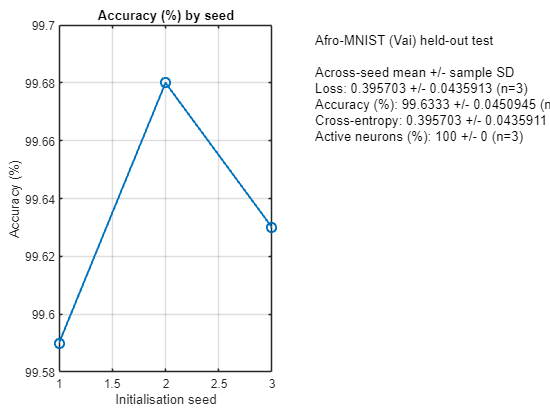

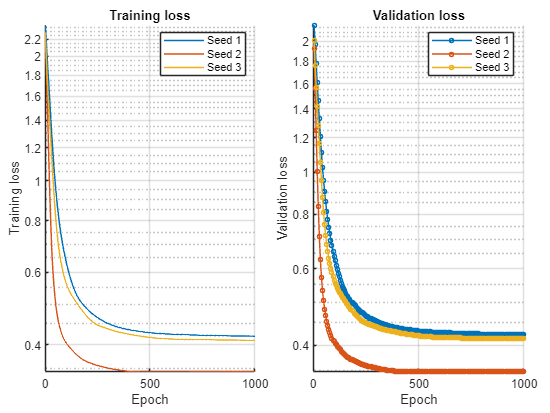

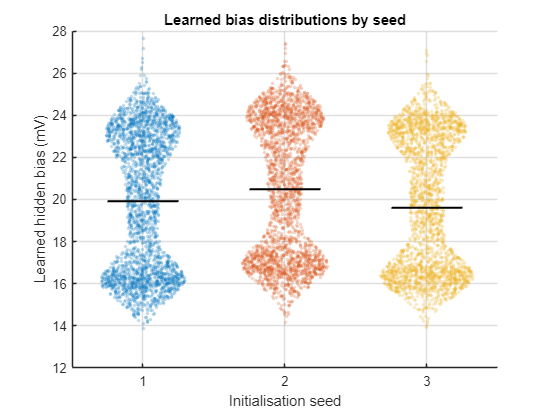

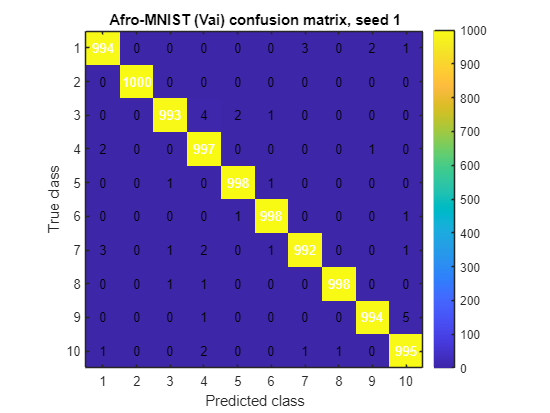

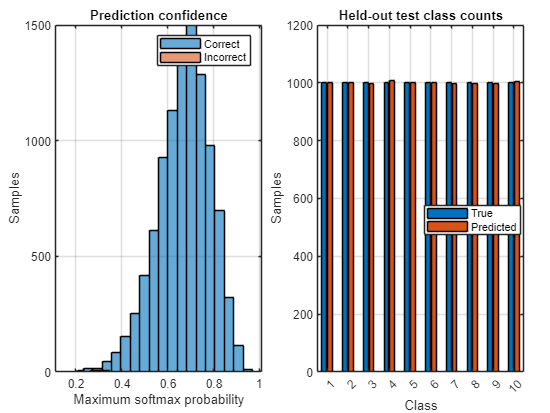

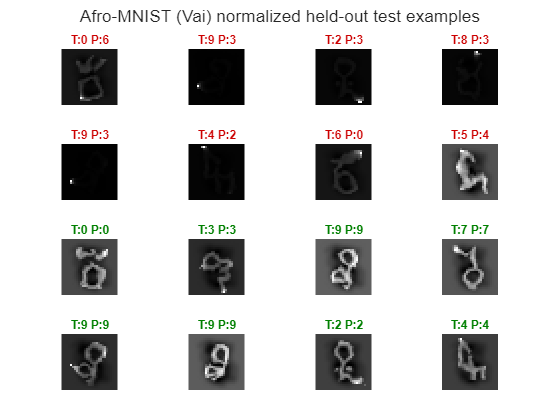

Exact full-held-out test current magnitudes (RMS over neurons, samples and time)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"       2.0014            0.51849                0.2

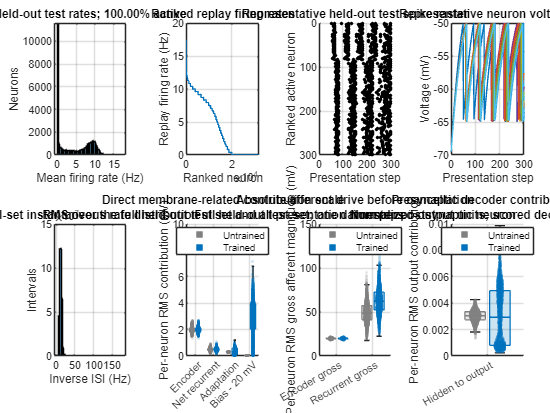

Current comparison: all 10000 held-out test samples and 300 presentation steps (3e+06 observations per neuron and condition).


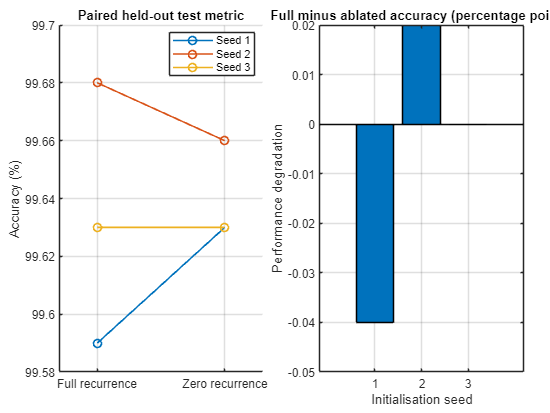

report = banff_evaluate_task("afro_mnist_vai", seeds, profile, overrides, display_options);

## Machine-readable results

report.seed_table

ans = 3×5 table
    Seed     Loss      AccuracyPercent    CrossEntropy    ActiveNeuronPercent
    ____    _______    _______________    ____________    ___________________

     1      0.42139         99.59           0.42139               100        
     2      0.34537         99.68           0.34537               100        
     3      0.42035         99.63           0.42035               100        


report.summary_table

ans = 4×4 table
           Metric             Mean     SampleSD    FiniteN
    _____________________    ______    ________    _______

    "Loss"                   0.3957    0.043591       3   
    "AccuracyPercent"        99.633    0.045095       3   
    "CrossEntropy"           0.3957    0.043591       3   
    "ActiveNeuronPercent"       100           0       3   


report.network_seed_audit

ans = 3×4 table
    Seed                                                                 ModelFile                                                                                            CheckpointHash                                                    FixedNetworkProbeHash                       
    ____    ____________________________________________________________________________________________________________________________________    __________________________________________________________________    __________________________________________________________________

     1      "/home/kai.mason/Documents/BANFF_SNN_pub/outputs/models/afro_mnist_vai_eprop_low_rank_hard_spike_N32000_cfgb471539af244_seed001.mat"    "71cb630d21ee85048e0222072aecea01d316db4348470e665aea4b6466314664"    "8a03c9aaadeea75965e2aaf6a814128d01ed96aed177397bd059855054